# Simple linear regression implementation

#### Data loading

load accidents
x = hwydata(:,14); %Population of states
y = hwydata(:,4); %Accidents per state
format long;

#### **Linear regression without interception**

% find a1 s.t. the linear regression relation y = a1 * x
a1 = x\y % The \ operator performs a least-squares regression.

a1 =      1.372716735564871e-04


#### Prediction and visualization

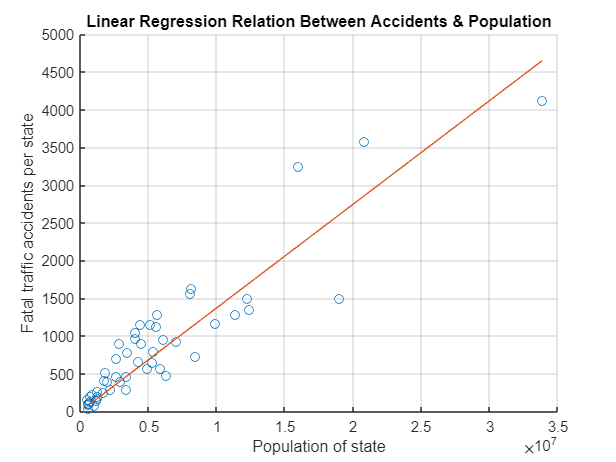

yCalc1 = a1*x;
scatter(x, y);
hold on;
plot(x, yCalc1);
xlabel('Population of state');
ylabel('Fatal traffic accidents per state');
title('Linear Regression Relation Between Accidents & Population');
grid on

#### **Linear regression with interception**

% find b s.t. the linear regression relation y = b1 * x + b2
X = [ones(length(x),1) x];
b = X\y

b = 1.0e+02 *

   1.427120171726538
   0.000001256394274


#### Prediction and visualization

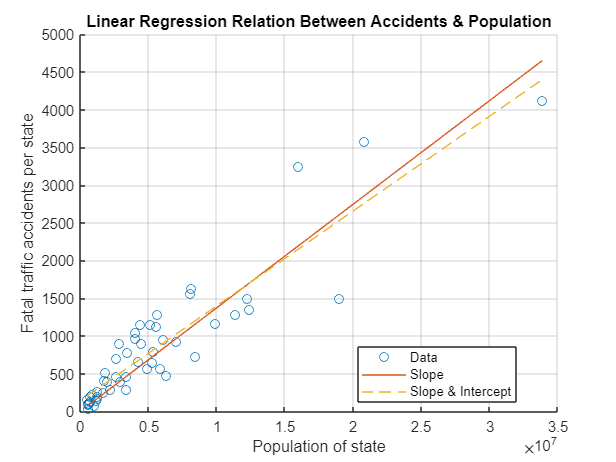

yCalc2 = X*b;
plot(x,yCalc2,'--')
legend('Data','Slope','Slope & Intercept','Location','best');